# Fit Second Order Underdamped Systems Graphically

The objective of these exercises is to fit parameters to describe a second order underdamped system. A second order system differential equation has an output $y(t)$, input $u(t)$ and four unknown parameters. The four parameters are the gain $K_p$, damping factor $\zeta$, second order time constant $\tau_s$, and dead time $\theta_p$.


$$\tau_s^2 \frac{d^2y}{dt^2} + 2 \zeta \tau_s \frac{dy}{dt} + y = K_p \, u\left(t-\theta_p \right)$$


The second order system can also be expressed in Laplace-domain form.


$$\frac{Y(s)}{U(s)} = \frac{K_p}{\tau_s^2 s^2 + 2 \zeta \tau_s s + 1}e^{-\theta_p s}$$


Where applicable, follow the steps to obtain a graphical approximation of a step response of an underdamped (oscillating) second order system. An underdamped system implies that $0 \ge \zeta > 1$.

- Find $\Delta y$ from step response.

- Find $\Delta u$ from step response.

- Calculate $K_p=\frac{\Delta y}{\Delta u}$.

- Calculate damping factor $\zeta$ from overshoot OS or decay ratio DR.

- Calculate $\tau_s$ from equations for rise time $t_r$, peak time $t_p$, or period P

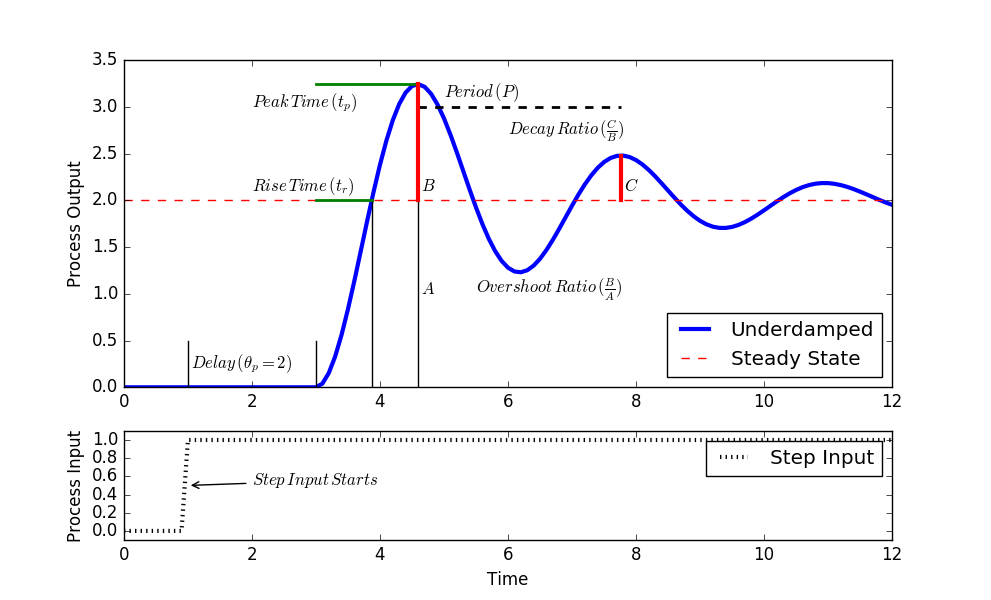

Assume a step input of 1.0 for each output graph for Exercises 1a-1c.

## Exercise 1

### 1a

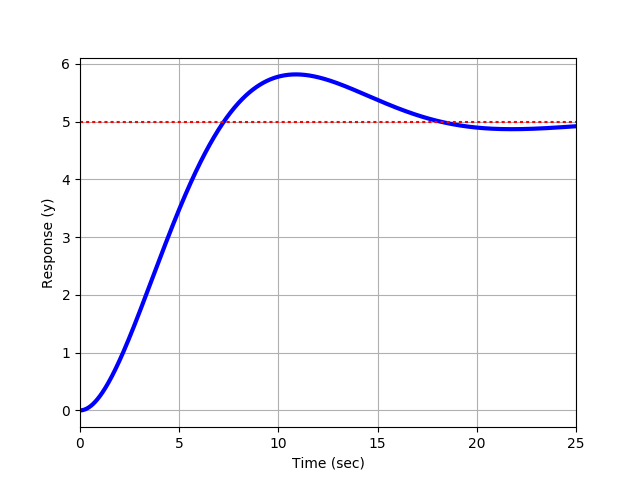

### 1b

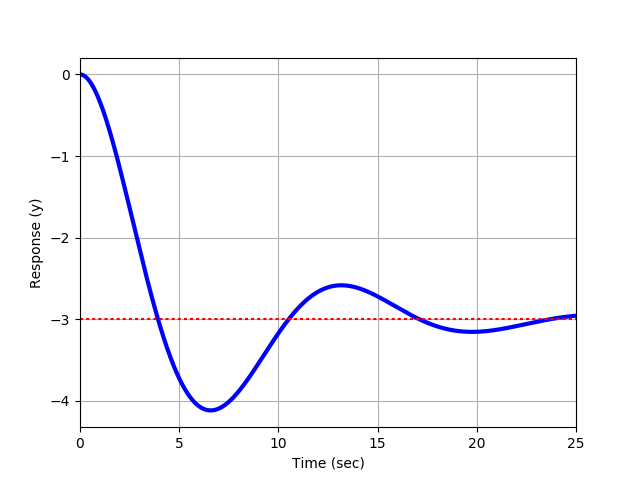

### 1c

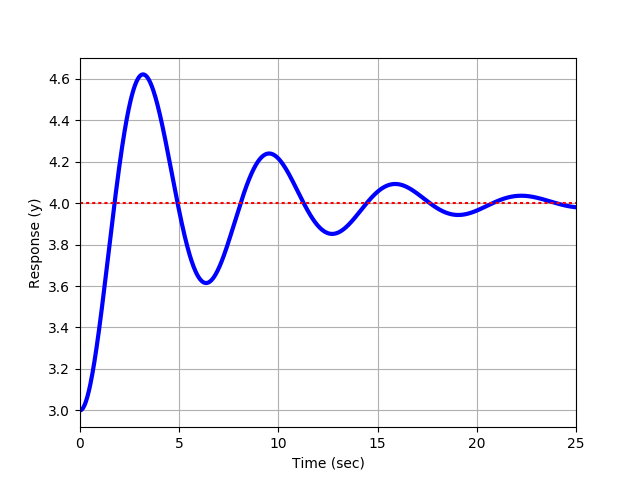

Use the following script to generate a step response for a 2nd order system. For each of the exercises (1a-1c), you can plug in the values for $K_p$, $\tau_s$, and zeta ($\zeta$) to generate a step response.

Kp = 1;
taus = 31.1;
zeta = 0.21;

% Create transfer function
num = [Kp];
den = [taus^2,2*zeta*taus,1];
[A,B,C,D] = tf2ss(num, den);

A =    -0.0135   -0.0010
    1.0000         0


B =      1
     0


C =          0    0.0010


D = 0

sys1 = ss(A,B,C,D);

sys1 =
 
  A = 
              x1         x2
   x1    -0.0135  -0.001034
   x2          1          0
 
  B = 
       u1
   x1   1
   x2   0
 
  C = 
             x1        x2
   y1         0  0.001034
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



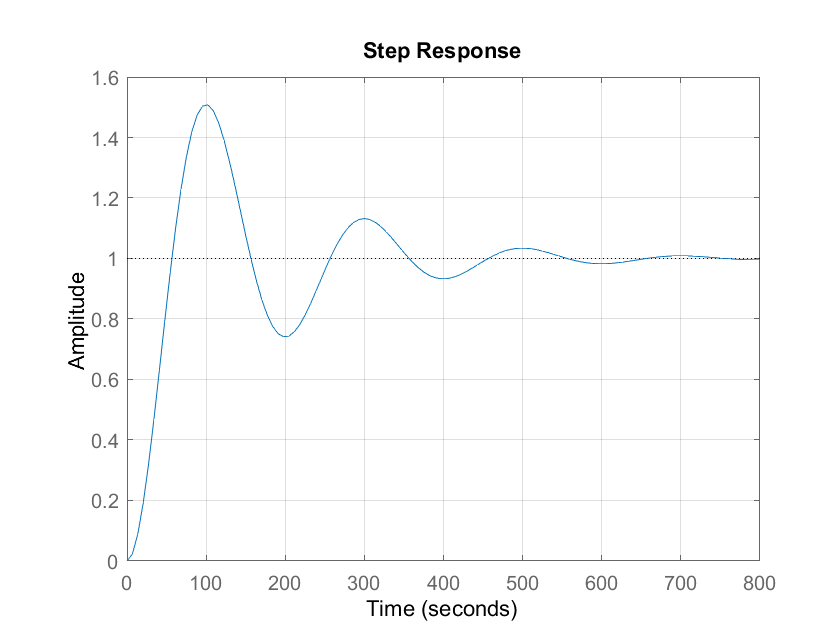


% simulate step change
figure()
t = linspace(0,25,250);
u = ones(1,250);
% lsim(sys1, u, t)
step(sys1)
grid on

## Problem 2

A PI closed loop controller process variable ($PV$) rises to meet a new set point ($SP$) following a change from 50 to 70. The $PV$ overshoots the new set point by 50% with two success peak values at 100 and 300 seconds after the set point change is initiated. The $PV$ response eventually settles to the new $SP$ with no offset. Determine the gain $K_p$, damping factor $\zeta$, and second order time constant $\tau_s$ that describe the closed loop response as a second order underdamped system. Assume that dead time $\theta_p$ is negligible.

## Solution

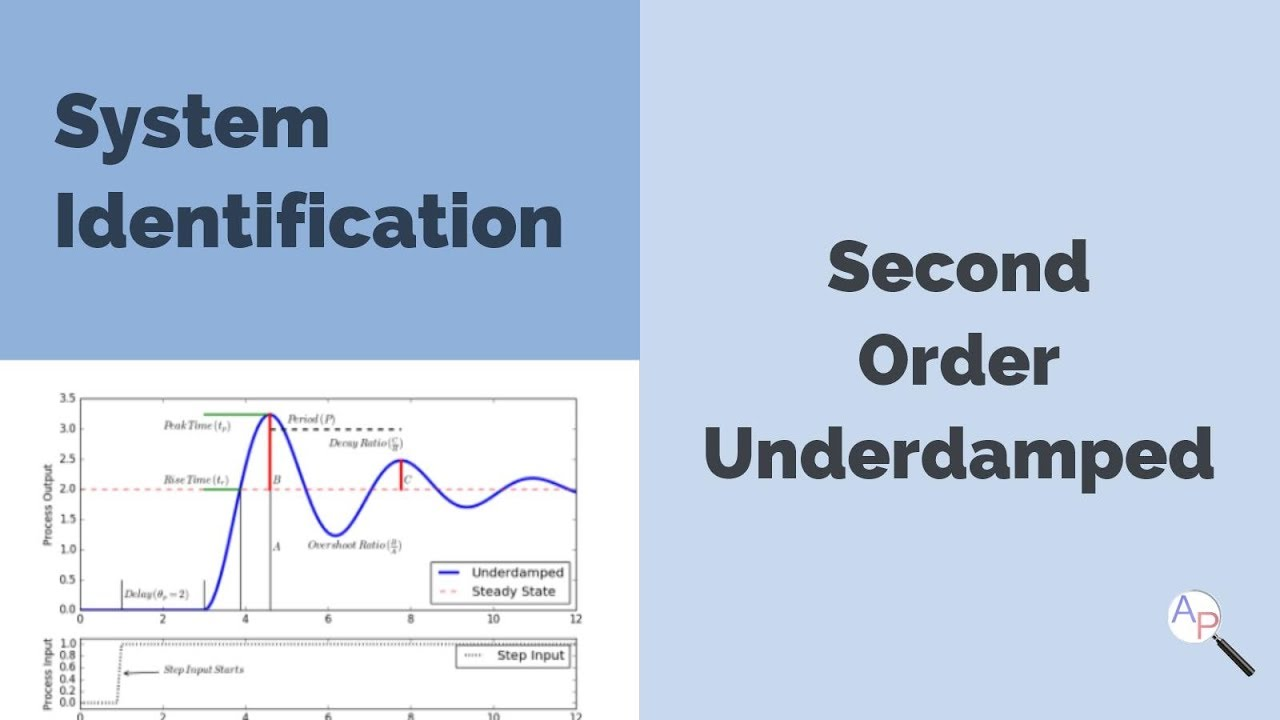

### [View Solution Video](https://www.youtube.com/watch?v=VLeq5Uql8o0)